Proof of functionality for "fixed" expression mode

**1.1) "Alpha" specifies mmol of enzyme secreted per g biomass growth**

Data with no enzyme decay or cell death

overwritefiles = true;

%use the data table "dat1" from paper_sections/data
t = dat1(dat1.decayrate == 0,:);
t = t(t.costfactor == 3,:);
t = sortrows(t,'alpha');

set(groot,'defaultLineLineWidth',2)
subplot(1,2,1);

plot(t.biomass{1},t.enzyme_amt{1},t.biomass{2},t.enzyme_amt{2},t.biomass{3},t.enzyme_amt{3})
title('Enzyme:Biomass Comparison')
leg = legend(num2str(t.alpha));
ltitle = get(leg,'title');
set(ltitle,'String','Alpha');
xlabel('Biomass (g)');
ylabel('Enzyme (mmol)');
slopeA = (t.enzyme_amt{1}(end) - t.enzyme_amt{1}(1)) / (t.biomass{1}(end) - t.biomass{1}(1))

slopeA = 0.0100

slopeB = (t.enzyme_amt{2}(end) - t.enzyme_amt{2}(1)) / (t.biomass{2}(end) - t.biomass{2}(1))

slopeB = 0.1000

slopeC = (t.enzyme_amt{3}(end) - t.enzyme_amt{3}(1)) / (t.biomass{3}(end) - t.biomass{3}(1))

slopeC = 1.0000

1.1a) The production rate is constant over a range of biomasses for a given alpha, and is of the expected magnitude

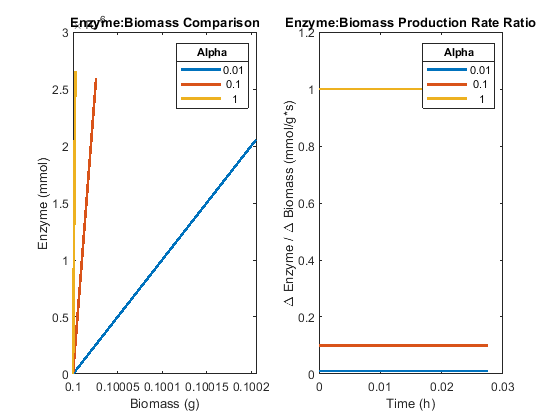

%plot(log10(t.biomass_delta{1}),log10(t.enzyme_delta{1}),log10(t.biomass_delta{2}),log10(t.enzyme_delta{2}),log10(t.biomass_delta{3}),log10(t.enzyme_delta{3}))
subplot(1,2,2);
plot(t.t{1}(1:end-1),t.enzyme_delta{1}./t.biomass_delta{1},t.t{2}(1:end-1),t.enzyme_delta{2}./t.biomass_delta{2},t.t{3}(1:end-1),t.enzyme_delta{3}./t.biomass_delta{3})
title('Enzyme:Biomass Production Rate Ratio')
leg = legend(num2str(t.alpha));
ltitle = get(leg,'title');
set(ltitle,'String','Alpha');
xlabel('Time (h)');
ylabel('\Delta Enzyme / \Delta Biomass (mmol/g*s)');

1.1b) The production rate is stable over time

**1.2) Cost factor behaves as expected**

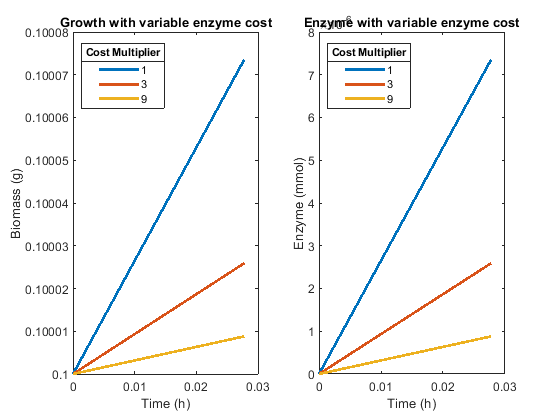

t = dat1(dat1.alpha == 0.1,:);
t = t(t.decayrate == 0,:);
t = sortrows(t,'costfactor');

%find the growth impact on each model
f = figure();
hold on;
subplot(1,2,1);
plot(t.t{1},t.biomass{1},t.t{2},t.biomass{2},t.t{3},t.biomass{3});
title('Growth with variable enzyme cost');
leg = legend(num2str(t.costfactor),'location','northwest');
ltitle = get(leg,'title');
set(ltitle,'String','Cost Multiplier');
xlabel('Time (h)');
ylabel('Biomass (g)');

subplot(1,2,2);
plot(t.t{1},t.enzyme_amt{1},t.t{2},t.enzyme_amt{2},t.t{3},t.enzyme_amt{3});
title('Enzyme with variable enzyme cost');
leg = legend(num2str(t.costfactor),'location','northwest');
ltitle = get(leg,'title');
set(ltitle,'String','Cost Multiplier');
xlabel('Time (h)');
ylabel('Enzyme (mmol)');

hold off;
if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\validate_costfactor.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\validate_costfactor.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\validate_costfactor.eps');%for LaTeX
end

biodelta = [(t.biomass{1}(end) - t.biomass{1}(1)); (t.biomass{2}(end) - t.biomass{2}(1)); (t.biomass{3}(end) - t.biomass{3}(1))];
enzdelta = [(t.enzyme_amt{1}(end) - t.enzyme_amt{1}(1)); (t.enzyme_amt{2}(end) - t.enzyme_amt{2}(1)); (t.enzyme_amt{3}(end) - t.enzyme_amt{3}(1))];
enz_bio_ratio = enzdelta ./ biodelta;
costfactor = t.costfactor;
biodelta_ratio = biodelta ./ min(biodelta);
enzdelta_ratio = enzdelta ./ min(enzdelta);
table_1_2a = table(costfactor, biodelta, enzdelta, enz_bio_ratio, biodelta_ratio, enzdelta_ratio)

table_1_2a = 3×6 table
    costfactor     biodelta      enzdelta     enz_bio_ratio    biodelta_ratio    enzdelta_ratio
    __________    __________    __________    _____________    ______________    ______________
        1         7.3586e-05    7.3586e-06         0.1             8.3528            8.3528    
        3         2.5927e-05    2.5927e-06         0.1              2.943             2.943    
        9         8.8097e-06    8.8097e-07         0.1                  1                 1    

Table 1.2A: The amount of growth and enzyme produced scales nearly to 1 / costfactor. The difference is likely due to the particular amino acid composition of the enzyme protein

finalbio = [t.biomass{1}(end) t.biomass{2}(end) t.biomass{3}(end)];
biodecrease = [finalbio(1) finalbio(1) finalbio(1)] - [t.biomass{1}(end) t.biomass{2}(end) t.biomass{3}(end)];
biodecrease_pct = finalbio ./ finalbio(1)

biodecrease_pct =     1.0000    0.9995    0.9994


finalenz = [t.enzyme_amt{1}(end) t.enzyme_amt{2}(end) t.enzyme_amt{3}(end)];
enzdecrease = [finalenz(1) finalenz(1) finalenz(1)] - [t.enzyme_amt{1}(end) t.enzyme_amt{2}(end) t.enzyme_amt{3}(end)];
enzdecrease_pct = finalenz ./ finalenz(1)

enzdecrease_pct =     1.0000    0.3523    0.1197


enzdecrease_fraction = {['1 / ' num2str(1/enzdecrease_pct(1))] ['1 / ' num2str(1/enzdecrease_pct(2))] ['1 / ' num2str(1/enzdecrease_pct(3))]}

enzdecrease_fraction = 1×3 cell array
    {'1 / 1'}    {'1 / 2.8382'}    {'1 / 8.3528'}

**1.3 Decay rate functions as expected**

We expect enzyme decay to follow first-order kinetics: A' = Ae^(-kt)

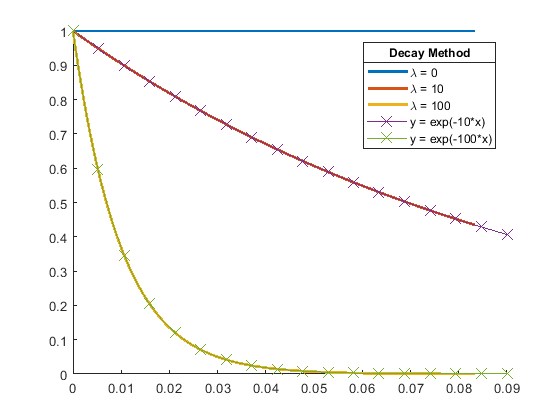

figure();
hold on;
plot(dat1b.t{1},dat1b.enzyme_amt{1},'-',dat1b.t{2},dat1b.enzyme_amt{2},'-',dat1b.t{3},dat1b.enzyme_amt{3},'-')

fplot(@(x) exp(-10*x),'-x','MarkerSize',10)
xlim([0 0.09])
ylim([0,1])
hold on
fplot(@(x) exp(-100*x),'-x','MarkerSize',10)
hold off
leg = legend({'\lambda = 0'; '\lambda = 10'; '\lambda = 100'; 'y = exp(-10*x)'; 'y = exp(-100*x)'});
ltitle = get(leg,'title');
set(ltitle,'String','Decay Method');
hold off;

%standard error and variance of the above
obs10 = arrayfun(@(x) exp(-10*x),dat1b.t{2});
obs100 = arrayfun(@(x) exp(-100*x),dat1b.t{3});
resid10 = obs10 - dat1b.enzyme_amt{2};
resid100 = obs100 - dat1b.enzyme_amt{3};

[r10,p10] = corrcoef(obs10,dat1b.enzyme_amt{2})

r10 =     1.0000    1.0000
    1.0000    1.0000


p10 =      1     0
     0     1


[r100,p100] = corrcoef(obs100,dat1b.enzyme_amt{3})

r100 =     1.0000    1.0000
    1.0000    1.0000


p100 =      1     0
     0     1


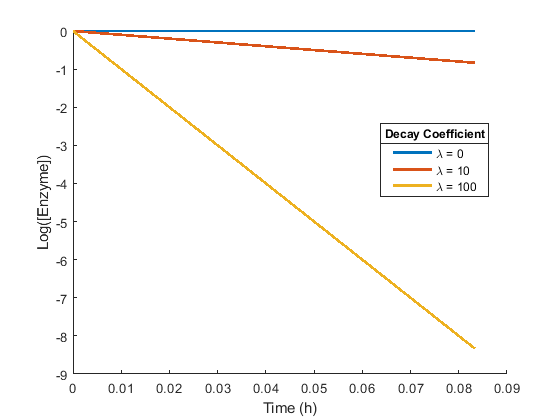

%As above, in semilog. The decays should make a straight line with slope = lambda
figure();
hold on;
plot(dat1b.t{1},log(dat1b.enzyme_amt{1}),'-',dat1b.t{2},log(dat1b.enzyme_amt{2}),'-',dat1b.t{3},log(dat1b.enzyme_amt{3}),'-')
% rline = refline(-10,0);
% rline.LineStyle = '--';
% rline = refline(-100,0);
% rline.LineStyle = '--';
% rline = refline(0,0);
% rline.LineStyle = '--';
%xlim([0 0.09])
%ylim([0,1])
leg = legend({'\lambda = 0'; '\lambda = 10'; '\lambda = 100'},'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','Decay Coefficient');
xlabel('Time (h)');
ylabel('Log([Enzyme])');
hold off;

**1.4 Cellulolysis proceeds at the desired rate**

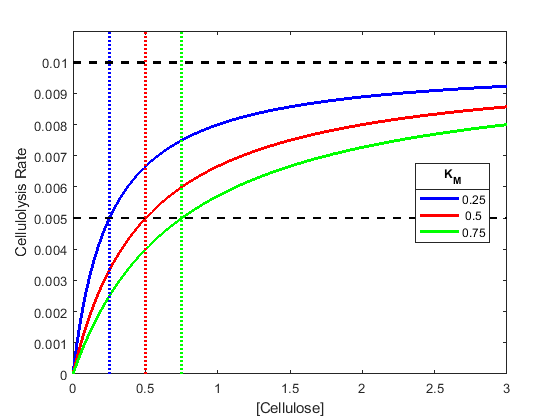

%KM Plots
kmdat = dat3(dat3.kcat == .1,:);
kmdat = sortrows(kmdat,'km');

hold off;

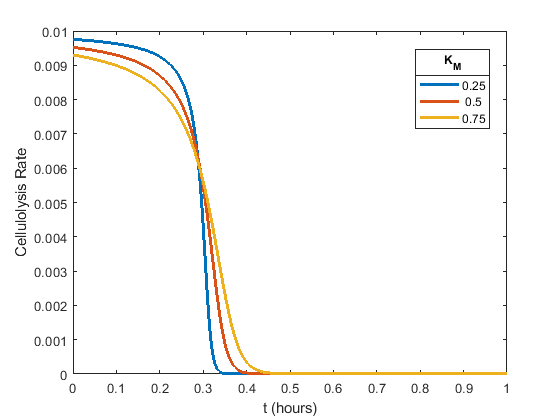

plot(kmdat.t{1}(1:end-1),-kmdat.cellulose_delta{1},kmdat.t{2}(1:end-1),-kmdat.cellulose_delta{2},kmdat.t{3}(1:end-1),-kmdat.cellulose_delta{3});
xlabel('t (hours)');
ylabel('Cellulolysis Rate');
leg = legend(num2str(kmdat.km),'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','K_M');

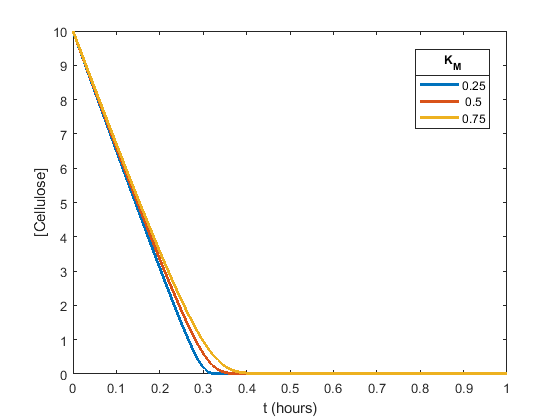

plot(kmdat.t{1},kmdat.cellulose_amt{1},kmdat.t{2},kmdat.cellulose_amt{2},kmdat.t{3},kmdat.cellulose_amt{3});
xlabel('t (hours)');
ylabel('[Cellulose]');
leg = legend(num2str(kmdat.km),'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','K_M');


f = figure();
plot(kmdat.cellulose_amt{1}(1:end-1),-kmdat.cellulose_delta{1},'-b',kmdat.cellulose_amt{2}(1:end-1),-kmdat.cellulose_delta{2},'-r',kmdat.cellulose_amt{3}(1:end-1),-kmdat.cellulose_delta{3},'-g')
xlabel('[Cellulose]');
ylabel('Cellulolysis Rate');
leg = legend(num2str(kmdat.km),'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','K_M');
hold on;
%indicate the half-saturation points and the theoretical max kcat
plot([kmdat.km(1) kmdat.km(1)],[0 .011],':b','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(1)/(1+kmdat.km(1)) .1*kmdat.kcat(1)/(1+kmdat.km(1))],'-.b','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(1)*kmdat.km(1)/(kmdat.km(1)+kmdat.km(1)) .1*kmdat.kcat(1)*kmdat.km(1)/(kmdat.km(1)+kmdat.km(1))],'-.b','HandleVisibility','off');
rline = refline(0, (.1 * kmdat.kcat(1) * kmdat.km(1))/(2 * kmdat.km(1)));
rline.LineStyle = '--';
rline.Color = 'k';
rline.HandleVisibility = 'off';
rline = refline(0, (.1 * kmdat.kcat(1)));
rline.LineStyle = '--';
rline.Color = 'k';
rline.HandleVisibility = 'off';
plot([kmdat.km(2) kmdat.km(2)],[0 .011],':r','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(2)/(1+kmdat.km(2)) .1*kmdat.kcat(2)/(1+kmdat.km(2))],'-.r','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(2)*kmdat.km(2)/(kmdat.km(2)+kmdat.km(2)) .1*kmdat.kcat(2)*kmdat.km(2)/(kmdat.km(2)+kmdat.km(2))],'-.r','HandleVisibility','off');
% rline = refline(0, (.1 * kmdat.kcat(2) * kmdat.km(2))/(2 * kmdat.km(2)));
% rline.LineStyle = '--';
% rline.Color = 'r';
plot([kmdat.km(3) kmdat.km(3)],[0 .011],':g','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(3)/(1+kmdat.km(3)) .1*kmdat.kcat(3)/(1+kmdat.km(3))],'-.g','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(3)*kmdat.km(3)/(kmdat.km(3)+kmdat.km(3)) .1*kmdat.kcat(3)*kmdat.km(3)/(kmdat.km(3)+kmdat.km(3))],'-.g','HandleVisibility','off');
% rline = refline(0, (.1 * kmdat.kcat(3) * kmdat.km(3))/(2 * kmdat.km(3)));
% rline.LineStyle = '--';
% rline.Color = 'g';
xlim([0 3])
ylim([0 0.011]);

%save the figure
if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\validate_mm.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\validate_mm.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\validate_mm.eps');%for LaTeX
end
hold off;


%KCAT PLOTS ------------------------------------------
kcatdat = dat3(dat3.km == .5,:);
kcatdat = sortrows(kcatdat,'kcat');

plot(kcatdat.t{1}(1:end-1),-kcatdat.cellulose_delta{1},kcatdat.t{2}(1:end-1),-kcatdat.cellulose_delta{2},kcatdat.t{3}(1:end-1),-kcatdat.cellulose_delta{3});
xlabel('t (hours)');
ylabel('Cellulolysis Rate');
leg = legend(num2str(kcatdat.kcat),'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','k_c_a_t');
subplot(1,2,1)
plot(kcatdat.t{1},kcatdat.cellulose_amt{1},kcatdat.t{2},kcatdat.cellulose_amt{2},kcatdat.t{3},kcatdat.cellulose_amt{3});
xlabel('t (hours)');
ylabel('[Cellulose]');
leg = legend(num2str(kcatdat.kcat),'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','k_c_a_t');
subplot(1,2,2)
plot(kcatdat.cellulose_amt{1}(1:end-1),-kcatdat.cellulose_delta{1},kcatdat.cellulose_amt{2}(1:end-1),-kcatdat.cellulose_delta{2},kcatdat.cellulose_amt{3}(1:end-1),-kcatdat.cellulose_delta{3})
xlabel('[Cellulose]');
ylabel('Cellulolysis Rate');
leg = legend(num2str(kcatdat.kcat),'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','k_c_a_t');